%%%%%%%%%%%%%%%%

graphSet;

repertoire = './'; % Chemin d'acces au code compile (NB: enlever le ./ sous Windows)
executable = 'Exercice7'; % Nom de l'executable (NB: ajouter .exe sous Windows)
input = '7_2_c.in'; % Nom du fichier d'entree de base

CFL = 0.9

CFL = 0.9000

u = 6

u = 6

t = 1.5

t = 1.5000

L = 20

L = 20

xtarg = 5

xtarg = 5


nsimul = 100

nsimul = 100


%N = linspace(50,1000,nsimul)
%N= 3.^ linspace(1,3,nsimul);
step = u * pi /L/10

step = 0.0942

N=0:step:(3.5*u*pi/L)

N =          0    0.0942    0.1885    0.2827    0.3770    0.4712    0.5655    0.6597    0.7540    0.8482    0.9425    1.0367    1.1310    1.2252    1.3195    1.4137    1.5080    1.6022    1.6965    1.7907    1.8850    1.9792    2.0735    2.1677    2.2619    2.3562    2.4504    2.5447    2.6389    2.7332    2.8274    2.9217    3.0159    3.1102    3.2044    3.2987


%N = [5 15 50]
%N= logspace(1,3.5, nsimul);
%N = reshape(((2.^[2:6])'*(5.^[1:4])),20,1)
paramstr = 'omega'; % Nom du parametre a scanner
paramstr2 = 'tfin'

paramstr2 = 'tfin'

nsimul2= 10

nsimul2 = 10

param = N; % Valeurs du parametre a scanner
nsimul = length(param);






output = cell(1, nsimul); % Tableau de cellules contenant le nom des fichiers de sortie
for i = 1:nsimul
    output{i} = [paramstr, '=', num2str(param(i) )];
    % Execution du programme en lui envoyant la valeur a scanner en argument
    cmd = sprintf('wsl %s%s %s  omega=%.15g output=%s tfin=%.15g', repertoire, executable, input,param(i),output{i},50);
    disp(cmd);
    system(cmd);
end

wsl ./Exercice7 7_2_c.in  omega=0 output=omega=0 tfin=50
wsl ./Exercice7 7_2_c.in  omega=0.0942477796076938 output=omega=0.094248 tfin=50
wsl ./Exercice7 7_2_c.in  omega=0.188495559215388 output=omega=0.1885 tfin=50
wsl ./Exercice7 7_2_c.in  omega=0.282743338823081 output=omega=0.28274 tfin=50
wsl ./Exercice7 7_2_c.in  omega=0.376991118430775 output=omega=0.37699 tfin=50
wsl ./Exercice7 7_2_c.in  omega=0.471238898038469 output=omega=0.47124 tfin=50
wsl ./Exercice7 7_2_c.in  omega=0.565486677646163 output=omega=0.56549 tfin=50
wsl ./Exercice7 7_2_c.in  omega=0.659734457253856 output=omega=0.65973 tfin=50
wsl ./Exercice7 7_2_c.in  omega=0.75398223686155 output=omega=0.75398 tfin=50
wsl ./Exercice7 7_2_c.in  omega=0.848230016469244 output=omega=0.84823 tfin=50
wsl ./Exercice7 7_2_c.in  omega=0.942477796076938 output=omega=0.94248 tfin=50
wsl ./Exercice7 7_2_c.in  omega=1.03672557568463 output=omega=1.0367 tfin=50
wsl ./Exercice7 7_2_c.in  omega=1.13097335529233 output=omega=1.131 tfin=50



eMax =zeros(4,nsimul);
nint = 3

nint = 3

tfin = zeros(1,nint);

for i = 1:nsimul % Parcours des resultats de toutes les simulations
    
    filename = output{i};
    data = load([filename,'_E.out']);
    E = data(:,2);
    t = data(:,1);
    
    
    intSize = floor(length(E)/nint);
    intervals= intSize : intSize : length(E);
    
    for j = 1:nint
    tfin(j) = t(intervals(j));
    eMax(i,j) = max(E(1:intervals(j)));
    end
    
end       



f=figure

f =   Figure (12) with properties:

      Number: 12
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [584 630 560 420]
       Units: 'pixels'

  Show all properties


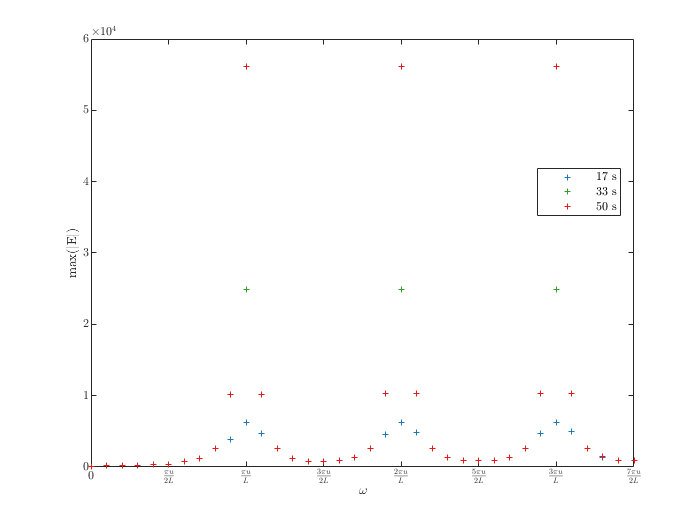

H = 5;
W = 8;
f.PaperUnits='centimeters';
f.InvertHardcopy='on';
f.PaperSize=[W H];
f.PaperPosition=[0 0 W H];
ax = axes(f,'Box','off');
for i = 1:nint
plot(ax,param,eMax(:,i),'+','MarkerSize',3,'MarkerEdgeColor',Colors{2*i},'DisplayName',[num2str(tfin(i),2) ' s'])
hold on
end
u = 6;

xticklabels({'0', '$\frac{\pi u}{2L}$', '$\frac{\pi u}{L}$', '$\frac{3\pi u}{2L}$' ,'$\frac{2\pi u}{L}$', '$\frac{5\pi u}{2L}$' ,'$\frac{3\pi u}{L}$' ,'$\frac{7\pi u}{2L}$' })
xticks((0:0.5:3.5)*u*pi/L)
xlim([0 3.5*u*pi/L ])
xlabel('$\omega$')
ylabel('max($\mid$E$\mid$)')
hold on;
legend('location','best','Fontsize',7)
ax.FontSize = 7;

print(f,'excitMax','-depsc2','-r300')

fsurfExcit = figure()

fsurfExcit =   Figure (24) with properties:

      Number: 24
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


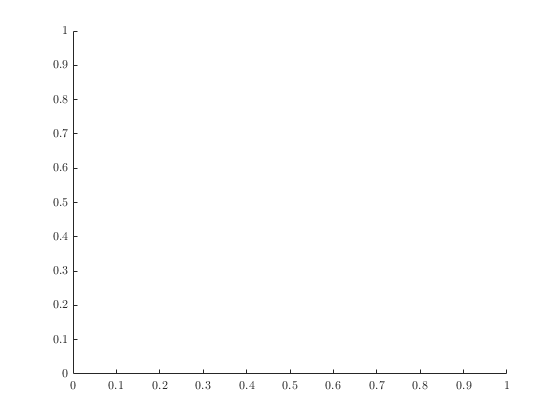

H = 5;
W = 8;
fsurfExcit.PaperUnits='centimeters';
fsurfExcit.InvertHardcopy='on';
fsurfExcit.PaperSize=[W H];
fsurfExcit.PaperPosition=[0 0 W H];

ax = axes(fsurfExcit,'Box','off');

loc = abs(N- 2*pi*u/L) < 0.01;


cmd = sprintf('wsl %s%s %s  omega=%.15g output=%s tfin=%.15g ecrire_f=1', repertoire, executable, input,param(loc),output{loc},50);
system(cmd);

	tfin=50
	L=20
	Npoints=500
	CFL=0.9
	type_u2=const
	u=6
0.0400802
0.00601202
	ecrire_f=1
	schema=A
	cb_gauche=harmonique
	cb_droit=fixe
	A=1
	omega=1.88496
	output=omega=1.885
	n_stride=1


filename = output{loc};
data = load([filename,'_f.out']);
fExcit = data(:,2:end);
data = load([filename,'_u.out']);
x = data(:,1);
data = load([filename,'_E.out']);
tExcit = data(:,1);
EExcit = data(:,2);

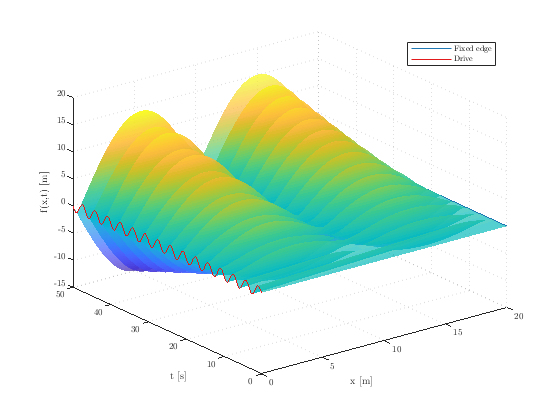

surf(x,tExcit,fExcit,'EdgeColor','none','FaceAlpha',0.7);
hold on;
z = zeros(size(t));
one = ones(size(t));
CondG = plot3(z,t,fExcit(:,1),'Color',M('dark red'));
CondD = plot3(20*one,t,z,'Color',M('dark blue'));
xlabel('x [m]');
ylabel('t [s]');
zlabel('f(x,t) [m]');
xlim([0 20]);
xticks(0:5:20)
yticks(0:10:50)
ylim([0 50]);
ax.FontSize = 7;
legend([CondD CondG],{'Fixed edge' 'Drive'},'Location','northeast','FontSize',6);


print(fsurfExcit,'surfExcit','-depsc2','-r300')

fsurfNonExcit = figure()

fsurfNonExcit =   Figure (25) with properties:

      Number: 25
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


H = 5;
W = 8;
fsurfNonExcit.PaperUnits='centimeters';
fsurfNonExcit.InvertHardcopy='on';
fsurfNonExcit.PaperSize=[W H];
fsurfNonExcit.PaperPosition=[0 0 W H];
ax = axes(fsurfNonExcit,'Box','off');


loc = abs(N- 1.5*pi*u/L) < 0.01;

cmd = sprintf('wsl %s%s %s  omega=%.15g output=%s tfin=%.15g ecrire_f=1', repertoire, executable, input,param(loc),output{loc},50);
system(cmd);

	tfin=50
	L=20
	Npoints=500
	CFL=0.9
	type_u2=const
	u=6
0.0400802
0.00601202
	ecrire_f=1
	schema=A
	cb_gauche=harmonique
	cb_droit=fixe
	A=1
	omega=1.41372
	output=omega=1.4137
	n_stride=1


filename = output{loc};
data = load([filename,'_f.out']);
f = data(:,2:end);
data = load([filename,'_u.out']);
x = data(:,1);
data = load([filename,'_E.out']);
t = data(:,1);
E = data(:,2);

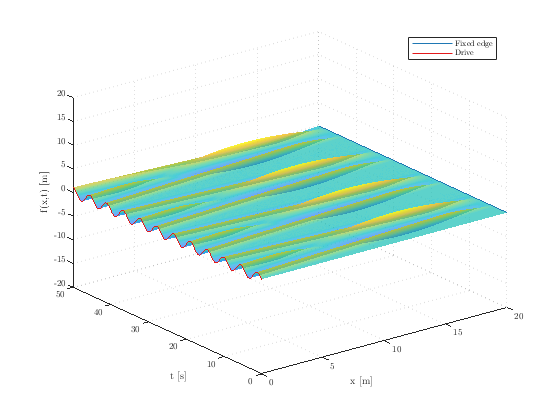

surf(x,t,f,'EdgeColor','none','FaceAlpha',0.7)
hold on;
z = zeros(size(t));
one = ones(size(t));
CondG = plot3(z,t,f(:,1),'Color',M('dark red'));
CondD = plot3(20*one,t,z,'Color',M('dark blue'));
zlim([-20 20])
xlabel('x [m]');
ylabel('t [s]');
zlabel('f(x,t) [m]');
xticks(0:5:20)
yticks(0:10:50)
xlim([0 20]);
ylim([0 50]);
ax.FontSize = 7;
legend([CondD CondG],{'Fixed edge' 'Drive'},'Location','best','FontSize',6);


print(fsurfNonExcit,'surfNonExcit','-depsc2','-r300')

fengExcit = figure()

fengExcit =   Figure (26) with properties:

      Number: 26
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


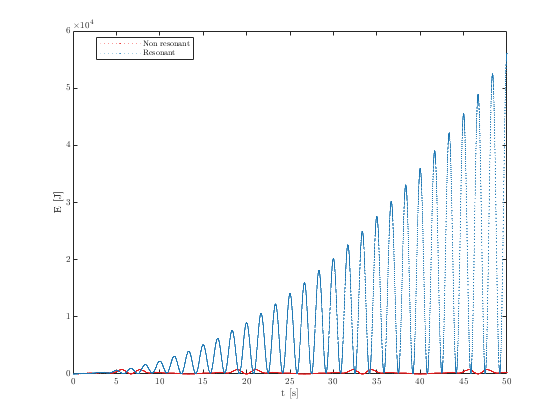


H = 5;
W = 8;
fengExcit.PaperUnits='centimeters';
fengExcit.InvertHardcopy='on';
fengExcit.PaperSize=[W H];
fengExcit.PaperPosition=[0 0 W H];
ax = axes(fengExcit,'Box','off');

plot(t,E,'.:','Markersize',3,'MarkerEdgeColor',M('dark red'),'Color',M('light red'),'DisplayName','Non resonant');
hold on;
plot(tExcit,EExcit,'.:','Markersize',3,'MarkerEdgeColor',M('dark blue'),'Color',M('light blue'),'DisplayName','Resonant');
xlim([0 50])
xlabel('t [s]')
ylabel('E [J]')
legend('location','best','Fontsize',6);
ax.FontSize = 7;

print(fengExcit,'engExcit','-depsc2','-r300')